# Create Deep Learning Network Architecture with Pretrained Parameters

Script for creating the layers for a deep learning network with the following properties:

Run the script to create the layers in the workspace variable `net`.

To learn more, see [Generate MATLAB Code From Deep Network Designer](matlab:helpview('deeplearning','generate_matlab_code')).

Auto-generated by MATLAB on 09-Sep-2025 18:38:25

## Load Network Parameters

Load network parameters like weights, biases, or layers unsupported for network code generation from the stored parameters file.

params = load("C:\MY FILES\Definately Not Acads\SIH\newtrain\params_2025_09_09__18_38_13.mat");

## Create dlnetwork

Create the dlnetwork variable to contain the network layers.

net = dlnetwork;

## Add Layer Branches

Add branches to the dlnetwork. Each branch is a linear array of layers.

tempNet = [
    imageInputLayer([16 16 200],"Name","imageinput","NormalizationDimension","channel")
    convolution2dLayer([1 1],128,"Name","conv_10","Padding","same")
    averagePooling2dLayer([5 5],"Name","avgpool2d","Padding","same")];
net = addLayers(net,tempNet);

tempNet = [
    convolution2dLayer([3 3],64,"Name","conv","Padding","same","Bias",params.conv.Bias,"Weights",params.conv.Weights)
    maxPooling2dLayer([3 3],"Name","maxpool","Padding","same")
    batchNormalizationLayer("Name","batchnorm","Offset",params.batchnorm.Offset,"Scale",params.batchnorm.Scale,"TrainedMean",params.batchnorm.TrainedMean,"TrainedVariance",params.batchnorm.TrainedVariance)];
net = addLayers(net,tempNet);

tempNet = [
    convolution2dLayer([1 1],64,"Name","conv_2","Padding","same","Bias",params.conv_2.Bias,"Weights",params.conv_2.Weights)
    reluLayer("Name","relu")];
net = addLayers(net,tempNet);

tempNet = [
    depthConcatenationLayer(3,"Name","depthcat")
    convolution2dLayer([3 3],64,"Name","conv_1","Padding","same","PaddingValue","replicate")
    reluLayer("Name","relu_5")
    convolution2dLayer([3 3],64,"Name","res2a_branch2a","BiasLearnRateFactor",0,"Padding",[1 1 1 1],"PaddingValue","replicate","Bias",params.res2a_branch2a.Bias,"Weights",params.res2a_branch2a.Weights)
    batchNormalizationLayer("Name","bn2a_branch2a","Offset",params.bn2a_branch2a.Offset,"Scale",params.bn2a_branch2a.Scale,"TrainedMean",params.bn2a_branch2a.TrainedMean,"TrainedVariance",params.bn2a_branch2a.TrainedVariance)
    reluLayer("Name","res2a_branch2a_relu")];
net = addLayers(net,tempNet);

tempNet = [
    convolution2dLayer([3 3],64,"Name","res2a_branch2b","BiasLearnRateFactor",0,"Padding",[1 1 1 1],"PaddingValue","replicate","Bias",params.res2a_branch2b.Bias,"Weights",params.res2a_branch2b.Weights)
    batchNormalizationLayer("Name","bn2a_branch2b","Offset",params.bn2a_branch2b.Offset,"Scale",params.bn2a_branch2b.Scale,"TrainedMean",params.bn2a_branch2b.TrainedMean,"TrainedVariance",params.bn2a_branch2b.TrainedVariance)
    reluLayer("Name","res2a_relu")];
net = addLayers(net,tempNet);

tempNet = [
    convolution2dLayer([3 3],64,"Name","res2b_branch2a","BiasLearnRateFactor",0,"Padding",[1 1 1 1],"Bias",params.res2b_branch2a.Bias,"Weights",params.res2b_branch2a.Weights)
    batchNormalizationLayer("Name","bn2b_branch2a","Offset",params.bn2b_branch2a.Offset,"Scale",params.bn2b_branch2a.Scale,"TrainedMean",params.bn2b_branch2a.TrainedMean,"TrainedVariance",params.bn2b_branch2a.TrainedVariance)
    reluLayer("Name","res2b_branch2a_relu")
    convolution2dLayer([3 3],64,"Name","res2b_branch2b","BiasLearnRateFactor",0,"Padding",[1 1 1 1],"Bias",params.res2b_branch2b.Bias,"Weights",params.res2b_branch2b.Weights)
    batchNormalizationLayer("Name","bn2b_branch2b","Offset",params.bn2b_branch2b.Offset,"Scale",params.bn2b_branch2b.Scale,"TrainedMean",params.bn2b_branch2b.TrainedMean,"TrainedVariance",params.bn2b_branch2b.TrainedVariance)];
net = addLayers(net,tempNet);

tempNet = [
    additionLayer(2,"Name","res2b")
    reluLayer("Name","res2b_relu")];
net = addLayers(net,tempNet);

tempNet = [
    convolution2dLayer([3 3],128,"Name","conv_11","Padding","same")
    batchNormalizationLayer("Name","bn3a_branch2a","Offset",params.bn3a_branch2a.Offset,"Scale",params.bn3a_branch2a.Scale,"TrainedMean",params.bn3a_branch2a.TrainedMean,"TrainedVariance",params.bn3a_branch2a.TrainedVariance)
    reluLayer("Name","res3a_branch2a_relu")
    convolution2dLayer([3 3],128,"Name","res3a_branch2b","BiasLearnRateFactor",0,"Padding",[1 1 1 1],"Bias",params.res3a_branch2b.Bias,"Weights",params.res3a_branch2b.Weights)
    batchNormalizationLayer("Name","bn3a_branch2b","Offset",params.bn3a_branch2b.Offset,"Scale",params.bn3a_branch2b.Scale,"TrainedMean",params.bn3a_branch2b.TrainedMean,"TrainedVariance",params.bn3a_branch2b.TrainedVariance)];
net = addLayers(net,tempNet);

tempNet = [
    convolution2dLayer([1 1],128,"Name","conv_12","Padding","same")
    batchNormalizationLayer("Name","bn3a_branch1","Offset",params.bn3a_branch1.Offset,"Scale",params.bn3a_branch1.Scale,"TrainedMean",params.bn3a_branch1.TrainedMean,"TrainedVariance",params.bn3a_branch1.TrainedVariance)];
net = addLayers(net,tempNet);

tempNet = [
    concatenationLayer(3,2,"Name","concat")
    averagePooling2dLayer([5 5],"Name","avgpool2d_1","Padding","same")];
net = addLayers(net,tempNet);

tempNet = [
    convolution2dLayer([3 3],64,"Name","conv_8","Padding","same","Bias",params.conv_8.Bias,"Weights",params.conv_8.Weights)
    maxPooling2dLayer([3 3],"Name","maxpool_1","Padding","same")
    batchNormalizationLayer("Name","batchnorm_1","Offset",params.batchnorm_1.Offset,"Scale",params.batchnorm_1.Scale,"TrainedMean",params.batchnorm_1.TrainedMean,"TrainedVariance",params.batchnorm_1.TrainedVariance)];
net = addLayers(net,tempNet);

tempNet = [
    convolution2dLayer([1 1],64,"Name","conv_9","Padding","same","Bias",params.conv_9.Bias,"Weights",params.conv_9.Weights)
    reluLayer("Name","relu_4")];
net = addLayers(net,tempNet);

tempNet = [
    depthConcatenationLayer(4,"Name","depthcat_1")
    convolution2dLayer([1 1],64,"Name","conv_3","Padding","same","Bias",params.conv_3.Bias,"Weights",params.conv_3.Weights)
    reluLayer("Name","relu_1")
    convolution2dLayer([1 1],64,"Name","conv_4","BiasLearnRateFactor",0.01,"Padding","same","WeightL2Factor",0.7,"WeightLearnRateFactor",0.01,"Bias",params.conv_4.Bias,"Weights",params.conv_4.Weights)
    clippedReluLayer(3,"Name","clippedrelu")
    convolution2dLayer([1 1],64,"Name","conv_5","BiasLearnRateFactor",0.1,"Padding","same","WeightL2Factor",10,"WeightLearnRateFactor",0.1)
    reluLayer("Name","relu_2")
    convolution2dLayer([1 1],32,"Name","conv_6","Padding","same","WeightL2Factor",10)
    reluLayer("Name","relu_3")
    convolution2dLayer([1 1],16,"Name","conv_7","Padding","same","WeightL2Factor",10)
    softmaxLayer("Name","softmax")];
net = addLayers(net,tempNet);

% clean up helper variable
clear tempNet;

## Connect Layer Branches

Connect all the branches of the network to create the network graph.

net = connectLayers(net,"avgpool2d","conv");
net = connectLayers(net,"avgpool2d","conv_2");
net = connectLayers(net,"avgpool2d","depthcat/in3");
net = connectLayers(net,"batchnorm","depthcat/in2");
net = connectLayers(net,"relu","depthcat/in1");
net = connectLayers(net,"res2a_branch2a_relu","res2a_branch2b");
net = connectLayers(net,"res2a_branch2a_relu","depthcat_1/in3");
net = connectLayers(net,"res2a_relu","res2b_branch2a");
net = connectLayers(net,"res2a_relu","res2b/in2");
net = connectLayers(net,"bn2b_branch2b","res2b/in1");
net = connectLayers(net,"bn2b_branch2b","depthcat_1/in4");
net = connectLayers(net,"res2b_relu","conv_11");
net = connectLayers(net,"res2b_relu","conv_12");
net = connectLayers(net,"bn3a_branch2b","concat/in1");
net = connectLayers(net,"bn3a_branch1","concat/in2");
net = connectLayers(net,"avgpool2d_1","conv_8");
net = connectLayers(net,"avgpool2d_1","conv_9");
net = connectLayers(net,"batchnorm_1","depthcat_1/in2");
net = connectLayers(net,"relu_4","depthcat_1/in1");
net = initialize(net);

## Plot Layers

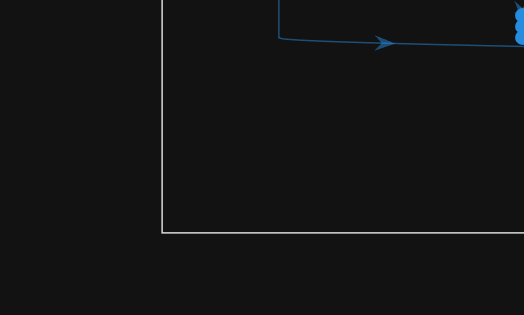

plot(net);

idx = randperm(100);
train_idx = idx(1:50);
val_idx = idx(51:80);
test_idx = idx(81:100);

% Then use as above.

% Split datalabels: 16x16x16xN
datalabels_train = datalabels(:,:,:,train_idx);
datalabels_val   = datalabels(:,:,:,val_idx);
datalabels_test  = datalabels(:,:,:,test_idx);

% Split datapatches: 16x16x200xN
datapatches_train = datapatches(:,:,:,train_idx);
datapatches_val   = datapatches(:,:,:,val_idx);
datapatches_test  = datapatches(:,:,:,test_idx);

    Iteration    Epoch    TimeElapsed    LearnRate    TrainingLoss    ValidationLoss
    _________    _____    ___________    _________    ____________    ______________
            0        0       00:00:00        0.001                            2.7725
            1        1       00:00:01        0.001          2.6898                  
           10        4       00:00:05        0.001               2            2.2522
           20        7       00:00:08        0.001          1.8373            1.8886
           30       10       00:00:11        0.001          1.5506            1.7465
           40       14       00:00:14        0.001          1.6519            1.6873
           50       17       00:00:17        0.001          1.1436            1.6911
           60       20       00:00:20        0.001          1.1793            1.6804
           70       24       00:00:24        0.001          1.2523            1.5888
           80       27       00:00:27        0.001          1.048

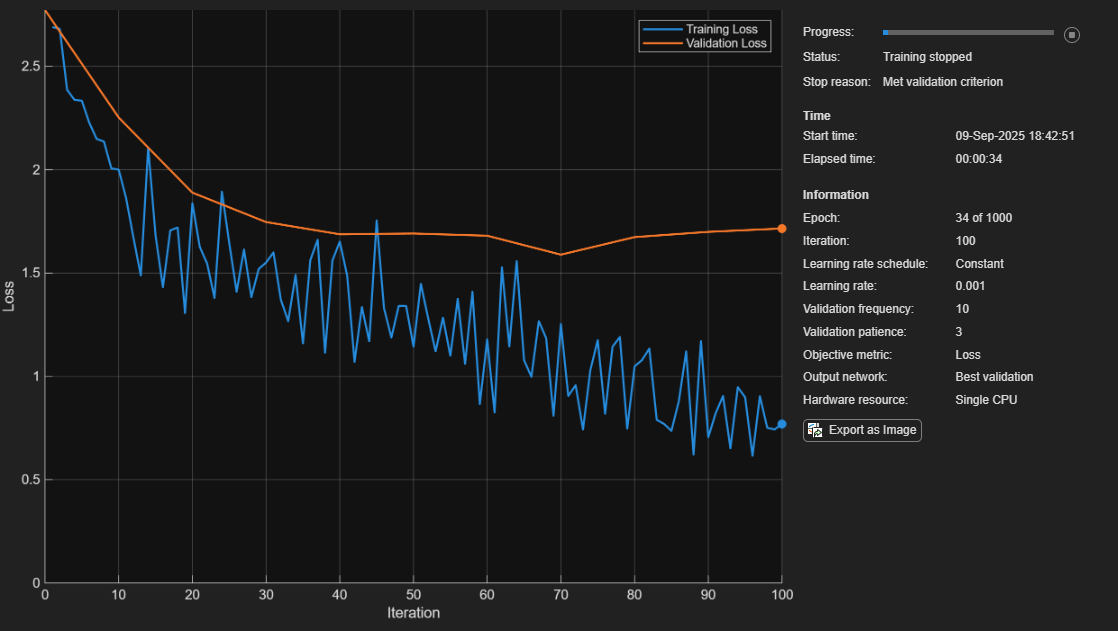

options = trainingOptions('adam', ...
    'MaxEpochs',1000, ...
    'MiniBatchSize',16, ...
    'Verbose',true, ...
    'Shuffle','every-epoch', ...
    'ValidationData',{datapatches_val, datalabels_val}, ...
    'ValidationFrequency',10,...
    'ValidationPatience',3,...
    'Plots','training-progress');

Trainednetonpines = trainnet(datapatches_train, datalabels_train, net,"crossentropy", options);

predictedLabels = Trainednetonpines.predict(datalabels_test(:,:,:,0));

Index in position 4 is invalid. Array indices must be positive integers or logical values.

testAccuracy = mean(predictedLabels == datalabels_test(:,:,:,0));
